# Exoskeleton assistive torque calculation considering ankle axis direction

## Symbolic Operations to Solve Assistive Forces

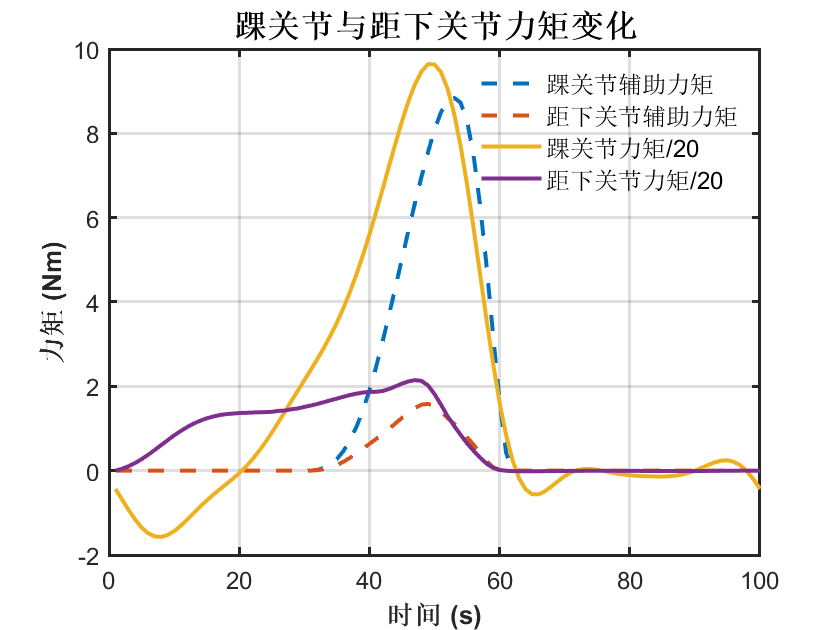

$$\left(\begin{array}{ccccccccccccc} \mathrm{Lleg} & {\mathrm{Ma}}_{d} & {\mathrm{Ms}}_{d} & \alpha_{\mathrm{add}} & \alpha_{\mathrm{fle}} & \alpha_{\mathrm{inv}} & \varphi_{a} & \varphi_{s} & \theta_{a} & \theta_{s} & {\mathrm{xp}}_{1} & {\mathrm{yp}}_{1} & {\mathrm{zp}}_{1} \end{array}\right)$$

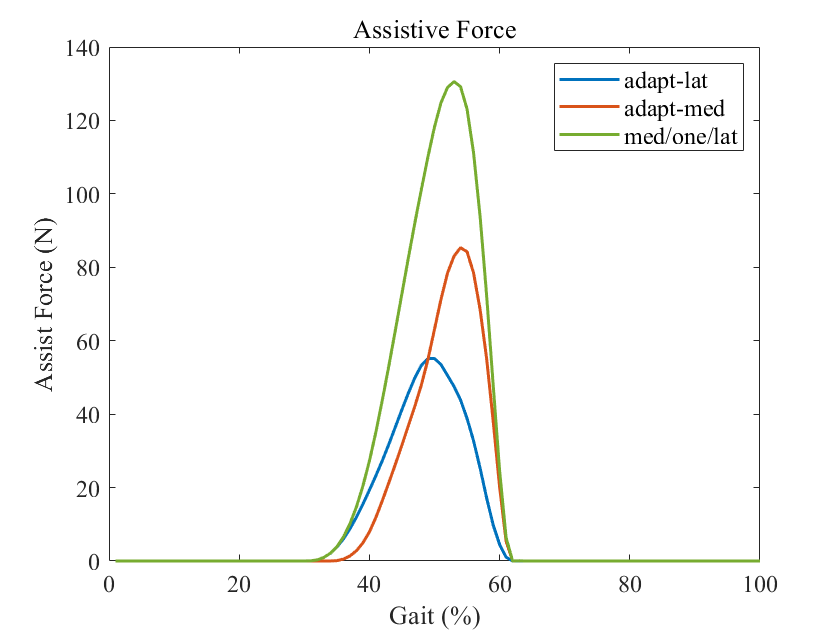

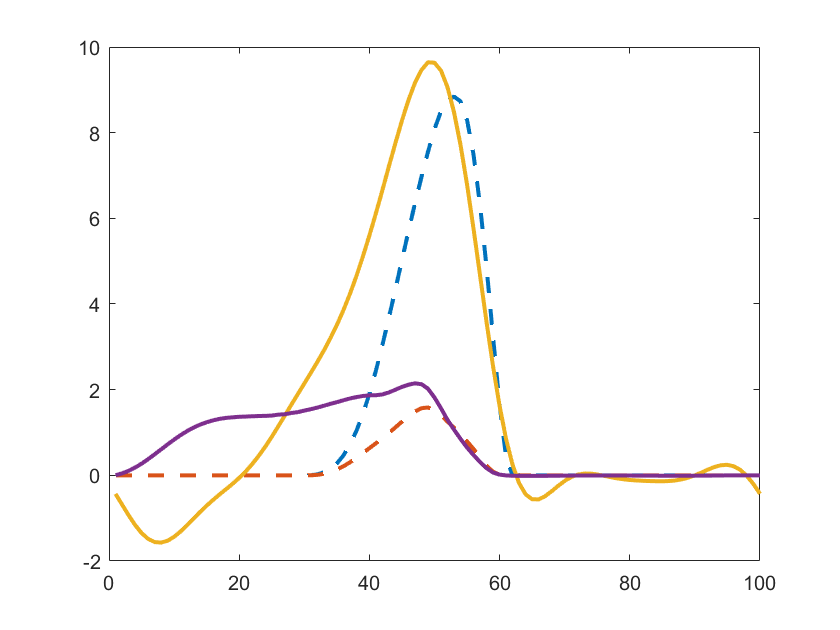

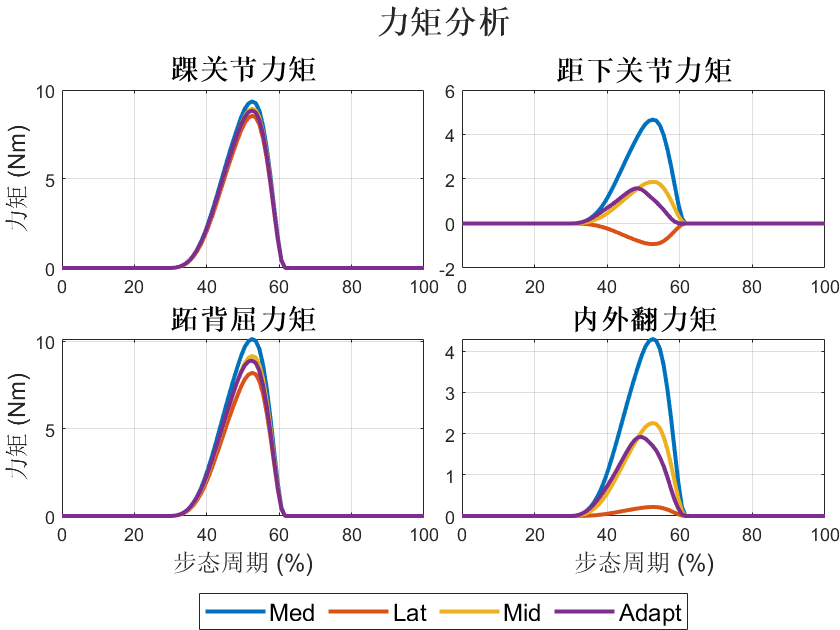

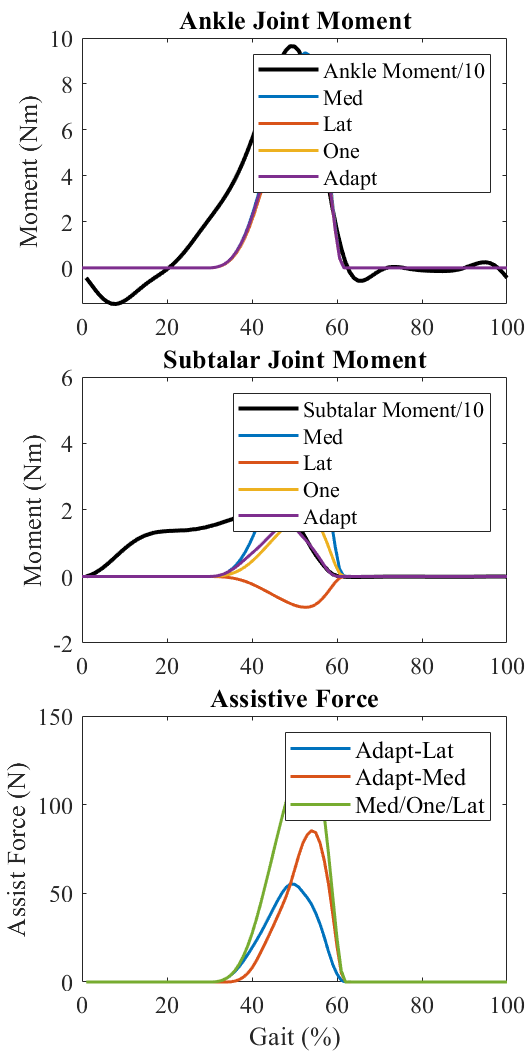


clear all

syms Lleg F1  xp1  yp1  zp1  theta_a phi_a theta_s phi_s  F2   alpha_fle alpha_inv alpha_add Mx_d My_d Ma_d Ms_d
assume([Lleg F1  xp1  yp1  zp1  theta_a phi_a theta_s phi_s  F2   alpha_fle alpha_inv alpha_add Mx_d My_d Ma_d Ms_d], 'real')

% Rotation matrices (ankle joint)
Rx=[1,0,0;0,cos(alpha_inv),-sin(alpha_inv);0,sin(alpha_inv),cos(alpha_inv)] ; % Inversion, x-axis
Ry=[cos(alpha_fle),0,sin(alpha_fle);0,1,0;-sin(alpha_fle),0,cos(alpha_fle)] ; % Dorsi/plantar flexion, y-axis
Rz=[cos(alpha_add),-sin(alpha_add),0;sin(alpha_add),cos(alpha_add),0;0,0,1] ; % Adduction, z-axis

r1 = [xp1, yp1, zp1 ]; % Force F1 application point
r1_=simplify(Rz*Ry*Rx*r1')';
r2 = [xp1, -yp1, zp1 ]; % Force F2 application point
r2_=simplify(Rz*Ry*Rx*r2')';
r12 = [ xp1, yp1, zp1+Lleg ]; % F1 leg attachment point
r22 = [ xp1,-yp1, zp1+Lleg ]; % F2 leg attachment point

F1_vector =F1*( r12 -r1_)/norm(r12 -r1_);
r_f1 = r1_ - [0, 0, 0];  
M_f1 = cross(r_f1, F1_vector); % Torque from F1

F2_vector =F2*(r22 -r2_)/norm(r22 -r2_);
r_f2 = r2_ - [0, 0, 0];
M_f2 = cross(r_f2, F2_vector); % Torque from F2

% Ankle axis unit vector
a_x = cos(phi_a) * sin(theta_a);
a_y = cos(phi_a) * cos(theta_a);
a_z = sin(phi_a);
unit_a = [a_x, a_y, a_z];
M1_a_proj = dot(M_f1, unit_a);
M1_a_x = simplify(M1_a_proj * unit_a(1)) ;
M1_a_y = simplify(M1_a_proj * unit_a(2));
M1_a_z = simplify(M1_a_proj * unit_a(3));
M1_a_simplified = simplify(M1_a_proj);

% Subtalar axis unit vector
s_x = cos(phi_s) * cos(theta_s);
s_y = cos(phi_s) * sin(theta_s);
s_z = sin(phi_s);
unit_s = [s_x, s_y, s_z];
M1_s_proj = dot(M_f1, unit_s);
M1_s_x = simplify(M1_s_proj * unit_s(1)) ;
M1_s_y = simplify(M1_s_proj * unit_s(2));
M1_s_z = simplify(M1_s_proj * unit_s(3));
M1_s_simplified = simplify(M1_s_proj);

M2_a_proj = dot(M_f2, unit_a);
M2_a_x = simplify(M2_a_proj * unit_a(1)) ;
M2_a_y = simplify(M2_a_proj * unit_a(2));
M2_a_z = simplify(M2_a_proj * unit_a(3));
M2_a_simplified = simplify(M2_a_proj);

M2_s_proj = dot(M_f2, unit_s);
M2_s_x = simplify(M2_s_proj * unit_s(1)) ;
M2_s_y = simplify(M2_s_proj * unit_s(2));
M2_s_z = simplify(M2_s_proj * unit_s(3)) ;
M2_s_simplified = simplify(M2_s_proj);

% Spatial torque components
Mx = simplify(M1_a_x +M1_s_x+ M2_a_x +M2_s_x);
My = simplify(M1_a_y +M1_s_y+ M2_a_y +M2_s_y);
Mz = simplify(M1_a_z +M1_s_z+ M2_a_z +M2_s_z);

Ma = simplify(M1_a_proj + M2_a_proj);
Ms = simplify(M1_s_proj + M2_s_proj);

% Solve for F1, F2 with torque equations
eq1 = Mx == Mx_d;
eq2 = My == My_d;
solution_Fj = solve([eq1, eq2], [F1,F2]);
F1_j=simplify(solution_Fj.F1);
F2_j=simplify(solution_Fj.F2);

eq1 = Ma == Ma_d;
eq2 = Ms == Ms_d;
solution_F = solve([eq1, eq2], [F1,F2]);
F1_d=simplify(solution_F.F1);
F2_d=simplify(solution_F.F2);

% save('assist_force.mat')